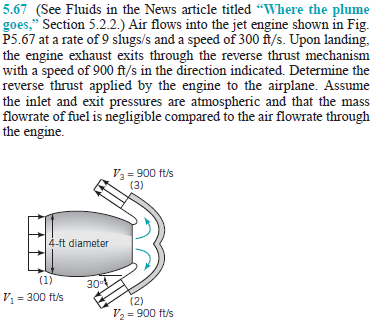

# inflow properties

u = symunit;
mdot1 = 9*u.slug/u.s;
D1 = 4*u.ft;
A1 = sympi*D1^2/4;
V1 = 300*u.ft/u.s;
V1x = V1;
V1y = 0;

# outflow properties

theta = 30*u.deg;
V2 = 900*u.ft/u.s;
V2x = V2*cos(theta);
V2y = V2*sin(theta);
V3 = 900*u.ft/u.s;
V3x = V3*cos(theta);
V3y = V3*sin(theta);

# conservation of mass

syms mdot2 mdot3;
eqn = sym.zeros(3,1);
eqn(1) = mdot1 == mdot2+mdot3;

# conservation of momentum (x-direction)

syms Fx;
eqn(2) = Fx == -mdot1*(V1x)+mdot2*(-V2x)+mdot3*(-V3x);

# conservation of momentum (y-direction)

eqn(3) = 0 == -mdot1*(V1y)+mdot2*(-V2y)+mdot3*(V3y);

# solution

eqn = simplify(eqn);
[Fx mdot2 mdot3] = solve(eqn, [Fx mdot2 mdot3]); %#ok
Fx = rewrite(simplify(Fx), u.lbf);
Fx_vpa = vpa(Fx, 6) %#ok

$$Fx\_vpa = -9714.81\,\mathrm{lbf}$$

clear Fx_vpa;